## Set 1: Kinematics (15 pts)

For this set, to receive credits for normal mode, you must do easy mode as well.

Given a 3-DOF Robot Manipulator 

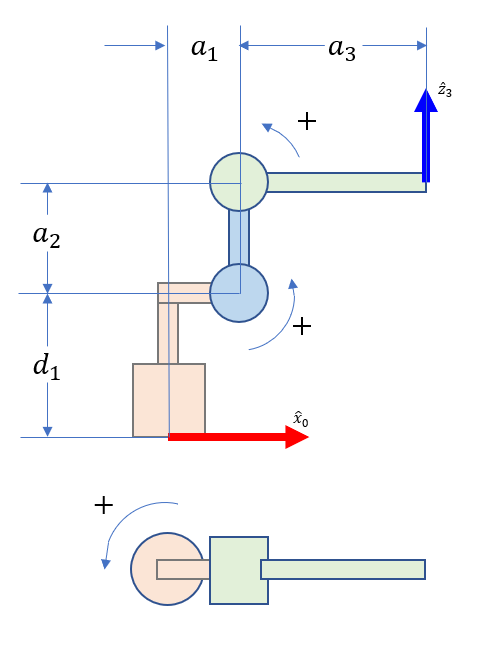

Figure 1: 3DOF Robot at Home Configuration

Easy Mode: (5 Points) 

- All neccesary coordinate frames

- DH Parameters in term of $a_1 ,a_2 ,a_3 ,d_1$

- Forward Kinematics Equation of every frames

- Inverse Kinematics of the end-effector

- Manipulator Jacobian of all frames

Implement 1-5 in MATLAB code. You may use the code from previous homeworks. Regardless, you must explain the workflow in detail.

Use the following parameters for the code.

Normal Mode: (10 Points) 

Show how to compute (1-5) by hand in MATLAB livescript and verify your result with MATLAB. To receive full credits, the result must match. 

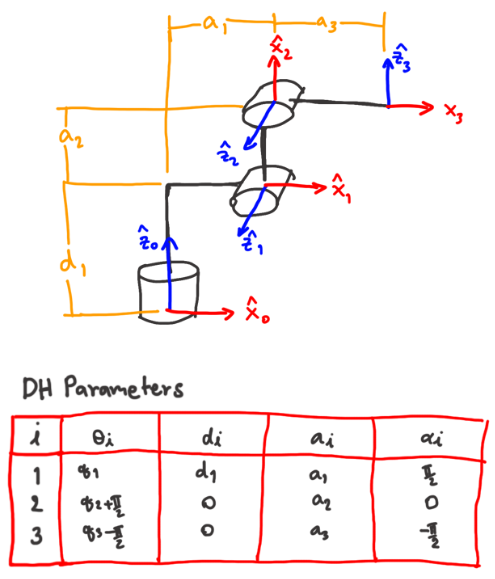

syms q1 q2 q3;
syms a1 a2 a3;
syms d1;
q = [q1 q2 q3];
rho = [1 1 1];
dh = [0 d1 a1 pi/2;pi/2 0 a2 0;-pi/2 0 a3 -pi/2]

$$dh = \left(\begin{array}{cccc} 0 & d_{1} & a_{1} & \frac{\pi }{2}\\ \frac{\pi }{2} & 0 & a_{2} & 0\\ -\frac{\pi }{2} & 0 & a_{3} & -\frac{\pi }{2} \end{array}\right)$$

F = forwardKinematicsSym(q,rho,dh)

$$\left(\begin{array}{cccc} \cos\left(q_{1}\right) & 0 & \sin\left(q_{1}\right) & a_{1}\,\cos\left(q_{1}\right)\\ \sin\left(q_{1}\right) & 0 & -\cos\left(q_{1}\right) & a_{1}\,\sin\left(q_{1}\right)\\ 0 & 1 & 0 & d_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$\begin{array}{l} \left(\begin{array}{cccc} -\cos\left(q_{1}\right)\,\sin\left(q_{2}\right) & -\cos\left(q_{1}\right)\,\cos\left(q_{2}\right) & \sin\left(q_{1}\right) & \cos\left(q_{1}\right)\,\sigma_{1}\\ -\sin\left(q_{1}\right)\,\sin\left(q_{2}\right) & -\cos\left(q_{2}\right)\,\sin\left(q_{1}\right) & -\cos\left(q_{1}\right) & \sin\left(q_{1}\right)\,\sigma_{1}\\ \cos\left(q_{2}\right) & -\sin\left(q_{2}\right) & 0 & d_{1}+a_{2}\,\cos\left(q_{2}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=a_{1}-a_{2}\,\sin\left(q_{2}\right) \end{array}$$

$$\begin{array}{l} \left(\begin{array}{cccc} \cos\left(q_{2}+q_{3}\right)\,\cos\left(q_{1}\right) & -\sin\left(q_{1}\right) & -\sin\left(q_{2}+q_{3}\right)\,\cos\left(q_{1}\right) & \cos\left(q_{1}\right)\,\sigma_{1}\\ \cos\left(q_{2}+q_{3}\right)\,\sin\left(q_{1}\right) & \cos\left(q_{1}\right) & -\sin\left(q_{2}+q_{3}\right)\,\sin\left(q_{1}\right) & \sin\left(q_{1}\right)\,\sigma_{1}\\ \sin\left(q_{2}+q_{3}\right) & 0 & \cos\left(q_{2}+q_{3}\right) & d_{1}+a_{3}\,\sin\left(q_{2}+q_{3}\right)+a_{2}\,\cos\left(q_{2}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=a_{1}+a_{3}\,\cos\left(q_{2}+q_{3}\right)-a_{2}\,\sin\left(q_{2}\right) \end{array}$$